% Sanaz Hami
% Rewriting Problem 2 Part (b) of Homework 9

% Set parameters for the simulation
a = 1;
b = 1;
T = 5;

errtab = zeros(5,2); % Storing error and convergence rate

% Define the initial condition function
f = @(x,y) sin(x+y);

% Iterate over different grid sizes
for ll = 1:size(errtab,1)
    % Define grid points based on current level
    Nx = 20*2^(ll-1)-1;
    Ny = Nx;
    hx = 2*pi/(Nx+1); hy = 2*pi/(Ny+1); % Grid spacing
    dt = hx*hx; % Time step calculation
    
    % Spatial grid setup
    x = 0:hx:2*pi - hx;
    y = 0:hy:2*pi - hy;
    [X,Y] = meshgrid(x,y);
    X = X'; Y = Y'; % Transpose for proper orientation

    % Initialize solution matrix with boundary conditions
    v = zeros(Nx+3, Ny+3);
    v(2:Nx+2, 2:Ny+2) = f(X, Y);
    % Apply periodic boundary conditions
    v(1,2:Ny+2) = v(Nx+2,2:Ny+2);
    v(Nx+3,2:Ny+2) = v(2,2:Ny+2);
    v(2:Nx+2,1) = v(2:Nx+2,Ny+2);
    v(2:Nx+2,Ny+3) = v(2:Nx+2,2);

    % Initialize matrix for new time step values
    v_new = zeros(size(v));

    % Time integration loop
    for kk = 1:floor(T/dt)
        % Update values using central difference scheme
        for ii = 2:Nx+2
            for jj = 2:Ny+2
                v_new(ii,jj) = v(ii,jj) - dt*a*(v(ii+1,jj)-v(ii-1,jj))/hx/2 - dt*b*(v(ii,jj+1)-v(ii,jj-1))/hy/2;
            end
        end
        % Update the solution matrix and reapply boundary conditions
        v = v_new;
        v(1,2:Ny+2) = v(Nx+2,2:Ny+2);
        v(Nx+3,2:Ny+2) = v(2,2:Ny+2);
        v(2:Nx+2,1) = v(2:Nx+2,Ny+2);
        v(2:Nx+2,Ny+3) = v(2:Nx+2,2);
    end

    % Handle the last time step
    dt_last = T - floor(T/dt)*dt;
    for ii = 2:Nx+2
        for jj = 2:Ny+2
            v_new(ii,jj) = v(ii,jj) - dt_last*a*(v(ii+1,jj)-v(ii-1,jj))/hx/2 - dt_last*b*(v(ii,jj+1)-v(ii,jj-1))/hy/2;
        end
    end
    v = v_new;

    % Calculate and store the error
    err = sqrt(hx*hy*sum(sum((f(X-a*T,Y-b*T)-v(2:Nx+2,2:Ny+2)).^2)));
    errtab(ll,1) = err;
end

% Compute the order of accuracy
for kk = 2:size(errtab,1)
    errtab(kk,2) = log(errtab(kk-1,1)/errtab(kk,1))/log(2);
end

% Display the error table
disp('Error Table:');

Error Table:


disp(errtab);

   7.1415e+00            0
   1.2530e+00   2.5108e+00
   2.8628e-01   2.1299e+00
   6.9982e-02   2.0324e+00
   1.7398e-02   2.0081e+00



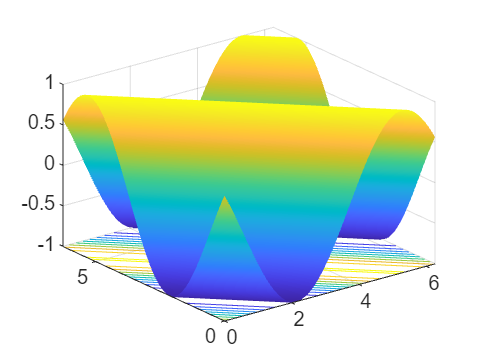

format shortE
% Visualize the solution
surfc(X,Y,v(2:Nx+2,2:Ny+2));
shading interp; % For smoother color transitions